The transfer matrix of the four tank system is considered as:

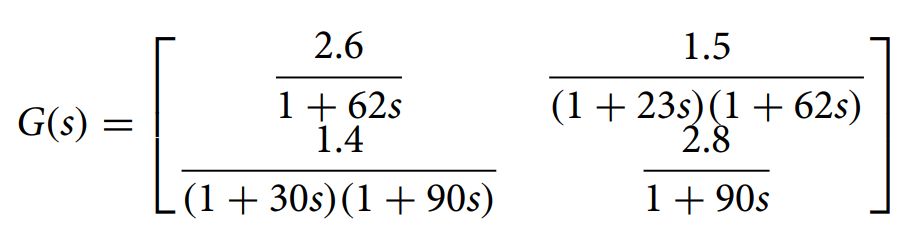

clear
s = tf('s');
G11 = 2.6/(1+62*s);
G12 = 1.5/(1+23*s)/(1+62*s);
G21 = 1.4/(1+30*s)/(1+90*s);
G22 = 2.8/(1+90*s);
G = [G11 G12; G21 G22];

MIMO_sys = MIMOSystem(G)

MIMO_sys =   MIMOSystem with properties:

             G: [2×2 tf]
        numOut: 2
         numIn: 2
           Kdc: [2×2 double]
           RGA: []
            Kc: []
       pairing: []
    sampleTime: []
            SR: []
      mpcParam: []


MIMO_sys.computeRGA;
MIMO_sys.staticRGA_analysis

Static RGA Analysis:
Relative Gain Array (Static):
    1.4054   -0.4054
   -0.4054    1.4054

Output 1 is best paired with Input 1 (RGA value: 1.41)
Output 2 is best paired with Input 2 (RGA value: 1.41)


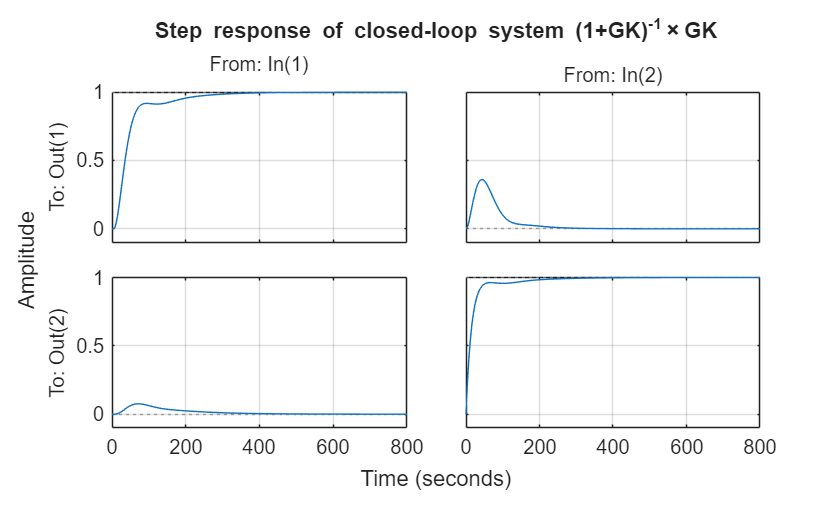

control1.model = "SOPTD"; % "FO" or "FOPTD" or "SO" or "SOPTD"
control1.tau = NaN;
control1.zeta = 0.8;
control1.wn = 0.05;
control1.theta = 5;
% ------------------------
control2.model = "FO";
control2.tau = 15;
control2.zeta = NaN;
control2.wn = NaN;
control2.theta = NaN;
% ------------------------
desiredCL = [control1, control2];
MIMO_sys.DirectSynthesis(desiredCL);
% Closed‑loop from reference to output: T(s) = KG/(1+KG)
K = MIMO_sys.Kc;

T = feedback(G*K, eye(size(G, 1)));    % unit negative feedback

% Step response
figure;
step(T);
grid on;
title('Step response of closed-loop system (1+GK)^{-1}\timesGK');

Recommended sample time: 2.3000 units
